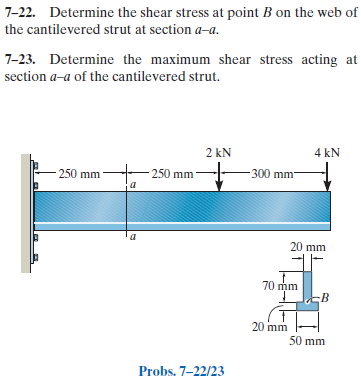

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-22P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-22P-solution-9780136022305) (problem 7-22)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-23P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-23P-solution-9780136022305) (problem 7-23)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R', 0);
b = b.add('reaction', 'moment', 'M', 0);
b = b.add('concentrated', 'force', -2*u.kN, 500*u.mm);
b = b.add('concentrated', 'force', -4*u.kN, 800*u.mm);
b.L = 800*u.mm;

# section properties

yc = [10 55]*u.mm;
Ac = [50*20 20*70]*u.mm^2;
Ic = [50*20^3 20*70^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = sum(In);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{25769803776\,x^{2}\,\left(x-2100\,\mathrm{mm}\right)}{46031311994879999\,\text{E}}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{4}} & \text{ if }x\leq 500\,\mathrm{mm}\\ -\frac{17179869184\,\left(-x^{3}+2400\,x^{2}\,\mathrm{mm}+375000\,x\,{\mathrm{mm}}^{2}-62500000\,{\mathrm{mm}}^{3}\right)}{46031311994879999\,\text{E}}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{4}} & \text{ if }500\,\mathrm{mm}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{77309411328\,x\,\left(x-1400\,\mathrm{mm}\right)}{46031311994879999\,\text{E}}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{4}} & \text{ if }x\leq 500\,\mathrm{mm}\\ -\frac{51539607552\,\left(-x^{2}+1600\,x\,\mathrm{mm}+125000\,{\mathrm{mm}}^{2}\right)}{46031311994879999\,\text{E}}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{4}} & \text{ if }500\,\mathrm{mm}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 6\,\left(x-700\,\mathrm{mm}\right)\,\mathrm{kN} & \text{ if }x\leq 500\,\mathrm{mm}\\ 4\,\left(x-800\,\mathrm{mm}\right)\,\mathrm{kN} & \text{ if }500\,\mathrm{mm}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 6\,\mathrm{kN} & \text{ if }x\leq 500\,\mathrm{mm}\\ 4\,\mathrm{kN} & \text{ if }500\,\mathrm{mm}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} M & 4200\,\mathrm{kN}\,\mathrm{mm}\\ R & 6\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

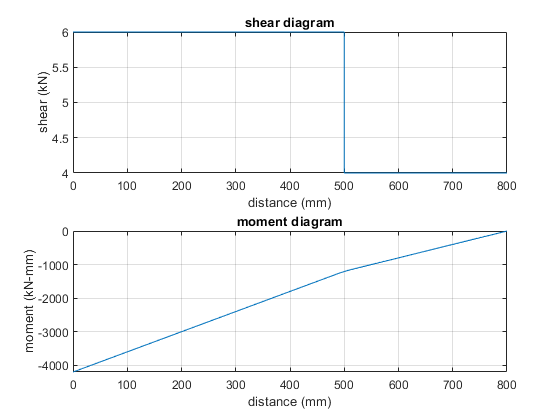

beam.shear_moment(m, v, [0 b.L], {'kN' 'mm'});

# shear stress at point B

V_B = v(250*u.mm);
Q_B = Qn(2);
t_B = 20*u.mm;
tau_B = rewrite(V_B*Q_B/(b.I*t_B), u.MPa);
tau_B_vpa = vpa(tau_B, 3) %#ok<NASGU> 

$$tau\_B\_vpa = 4.41\,\mathrm{MPa}$$

# maximum shear stress

V_max = v(250*u.mm);
Q_max = ((90*u.mm-yn)/2)*(20*u.mm)*(90*u.mm-yn);
t_min = 20*u.mm;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.MPa);
tau_max_vpa = vpa(tau_max, 3) %#ok<NASGU> 

$$tau\_max\_vpa = 4.85\,\mathrm{MPa}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear tau_B_vpa;
clear tau_max_vpa;